cd 'Z:\Projects\Martina_Berenil\Baseline model\raw data'
T_FID=readtable('FIDdata_refine.csv','PreserveVariableNames',true);
X = [T_FID.("glob"),T_FID.("Q_VSA_PNEG"),T_FID.("vsurf_DD23")];
y = T_FID.FID;
mdl_overall = fitlm(X,y)

mdl_overall = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)        3.1806      0.69271     4.5915    0.00041918
    x1                0.79948      0.44279     1.8056      0.092531
    x2                      0            0        NaN           NaN
    x3             -0.0050473    0.0016414    -3.0749     0.0082319


Number of observations: 18, Error degrees of freedom: 15
Root Mean Squared Error: 0.409
R-squared: 0.402,  Adjusted R-Squared: 0.322
F-statistic vs. constant model: 5.04, p-value = 0.0212

% LOOCV for the top model
yhat=zeros(size(T_FID,1),1);
for i=1:size(T_FID,1)
    X_test=X(i,:);
    y_test = y(i,:);
    X_train=X;
    X_train(i,:)=[];
    y_train=y;
    y_train(i,:)=[];
    mdl_loocv=fitlm(X_train,y_train);
    yhat(i)=predict(mdl_loocv,X_test);
end

%calculate Q2_loocv
Rsquare(y,yhat)

ans = 0.6752

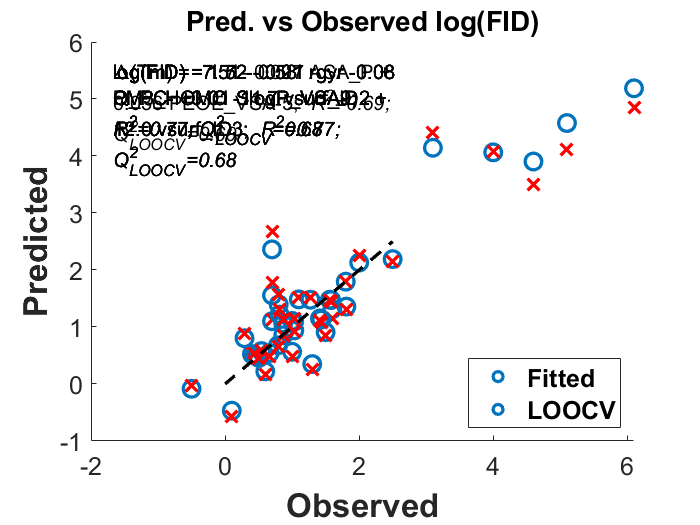

% plot the figure

scatter(y,mdl_overall.Fitted,100,'MarkerEdgeColor',[0.00 0.45 0.74], ...
    'MarkerFaceColor','none','LineWidth',2)
ax=gca;
ax.FontSize=15;
hold on
scatter(y,yhat,100,'x','MarkerEdgeColor',[1 0 0], ...
    'MarkerFaceColor','none','LineWidth',2)
x=linspace(0,2.5);
y=x;
plot(x,y,'LineWidth',2,'LineStyle',"--","Color",'k')
legend('Fitted','LOOCV','FontSize',15,'TextColor','k','Location','southeast', ...
    'FontWeight','bold')
title('Pred. vs Observed log(FID)','FontSize',20,'FontWeight',"bold")
xlabel('Observed log(FID)','FontSize',20,'FontWeight',"bold")
ylabel('Predicted log(FID)','FontSize',20,'FontWeight',"bold")
annotation('textbox',[0.15,0.8,0.45,0.1],'FontSize',12,'String', ...
    strcat('log(FID) = -0.945 + 3.29 glob +0.0687 Q\_VSA\_PNEG +0.0636 vsurf\_DD23', ...
    ';',{32},'\it R^2=0.87',';',{32}, ...
    'Q^2_{LOOCV}=0.74'),'EdgeColor','none');

T_Tm=readtable('Tmdata_refine.csv','PreserveVariableNames',true);
X = [T_Tm.("E_stb"),T_Tm.("Q_VSA_POL"),T_Tm.("SMR_VSA7")];
y = T_Tm.Tm;
mdl_overall = fitlm(X,y)

mdl_overall = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     -7.5074     1.9733    -3.8045     0.0014169
    x1             -0.57654    0.12735    -4.5271      0.000298
    x2              -11.747     1.8763    -6.2609    8.6155e-06
    x3               11.975     1.5712     7.6219    7.0114e-07


Number of observations: 21, Error degrees of freedom: 17
Root Mean Squared Error: 0.733
R-squared: 0.854,  Adjusted R-Squared: 0.828
F-statistic vs. constant model: 33.2, p-value = 2.5e-07

% LOOCV for the top model
yhat=zeros(size(T_Tm,1),1);
for i=1:size(T_Tm,1)
    X_test=X(i,:);
    y_test = y(i,:);
    X_train=X;
    X_train(i,:)=[];
    y_train=y;
    y_train(i,:)=[];
    mdl_loocv=fitlm(X_train,y_train);
    yhat(i)=predict(mdl_loocv,X_test);
end

%calculate Q2_loocv
Rsquare(y,yhat)

ans = 0.7679

% plot the figure

scatter(y,mdl_overall.Fitted,100,'MarkerEdgeColor',[0.00 0.45 0.74], ...
    'MarkerFaceColor','none','LineWidth',2)

Error using scatter (line 92)
X and Y must be vectors of the same length.

ax=gca;
ax.FontSize=15;
hold on
scatter(y,yhat,100,'x','MarkerEdgeColor',[1 0 0], ...
    'MarkerFaceColor','none','LineWidth',2)
x=linspace(-2,8);
y=x;
plot(x,y,'LineWidth',2,'LineStyle',"--","Color",'k')
legend('Fitted','LOOCV','FontSize',15,'TextColor','k','Location','southeast','FontWeight','bold')
title('Pred. vs Observed {\Delta}T_m','FontSize',20,'FontWeight',"bold")
xlabel('Observed {\Delta}T_m','FontSize',20,'FontWeight',"bold")
ylabel('Predicted {\Delta}T_m','FontSize',20,'FontWeight',"bold")
annotation('textbox',[0.15,0.8,0.45,0.1],'FontSize',12,'String', ...
    strcat('{\Delta}T_m = -4.11 - 1.28 E\_stb + 0.032 Q\_VSA\_POL + 0.0088 SMR\_VSA7',';',{32},'\it R^2=0.95',';',{32}, ...
    'Q^2_{LOOCV}=0.91'),'EdgeColor','none');

cd 'Z:\Projects\Martina_Berenil\Baseline model\raw data'
T_RNase=readtable('RNasedata_refine.csv','PreserveVariableNames',true);
X = [T_RNase.("std_dim3"),T_RNase.("CASA-"), T_RNase.("PM3_Eele"),T_RNase.("vsurf_DD23")];
y = T_RNase.RNase;
mdl_overall = fitlm(X,y)

mdl_overall = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        1.5358       0.49811     3.0834     0.0071239
    x1                 1.2191       0.31014     3.9307     0.0011941
    x2             0.00056476    0.00020928     2.6986      0.015816
    x3             3.2621e-06    5.0022e-07     6.5213    7.0441e-06
    x4              -0.079678      0.023974    -3.3236     0.0043001


Number of observations: 21, Error degrees of freedom: 16
Root Mean Squared Error: 0.438
R-squared: 0.743,  Adjusted R-Squared: 0.679
F-statistic vs. constant model: 11.6, p-value = 0.000131

% LOOCV for the top model
yhat=zeros(size(T_RNase,1),1);
for i=1:size(T_RNase,1)
    X_test=X(i,:);
    y_test = y(i,:);
    X_train=X;
    X_train(i,:)=[];
    y_train=y;
    y_train(i,:)=[];
    mdl_loocv=fitlm(X_train,y_train);
    yhat(i)=predict(mdl_loocv,X_test);
end

%calculate Q2_loocv
Rsquare(y,yhat)

ans = 0.6084

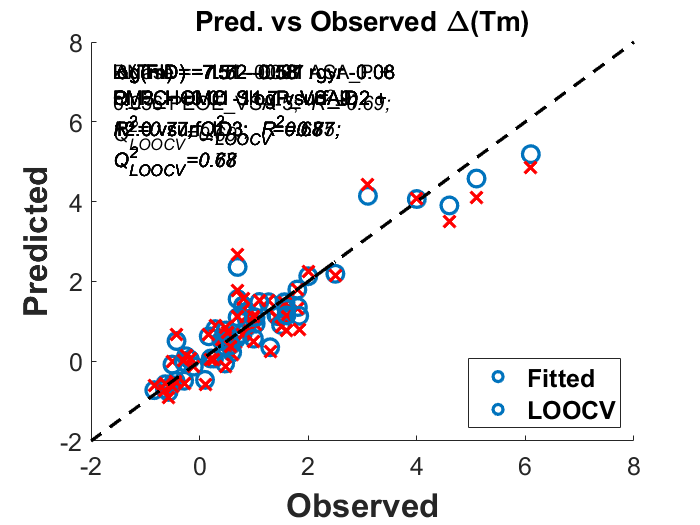

% fill the color for different regions

x_fill = [-2 -2 0 0];
y_fill = [-2 3 3 -2];
fill(x_fill,y_fill,[0.94,0.84,0.69],'HandleVisibility','off')

hold on 
x_fill = [0 0 3 3];
y_fill = [-2 3 3 -2];
fill(x_fill,y_fill,[0.69,0.84,0.94],'HandleVisibility','off')

% plot the figure
id_de=find(y>=0);
id_st=find(y<0);
scatter(y(id_de),mdl_overall.Fitted(id_de),100,'MarkerEdgeColor',[0.00 0.45 0.74], ...
    'MarkerFaceColor','none','LineWidth',2)
scatter(y(id_st),mdl_overall.Fitted(id_st),100,'MarkerEdgeColor',[0.98,0.34,0.11], ...
    'MarkerFaceColor','none','LineWidth',2)
ax=gca;
ax.FontSize=15;
hold on
scatter(y,yhat,100,'x','MarkerEdgeColor',[1 0 0], ...
    'MarkerFaceColor','none','LineWidth',2)
x=linspace(-2,3);
Y=x;
plot(x,Y,'LineWidth',2,'LineStyle',"--","Color",'k')
legend('Stabilizer','Destabilizer','LOOCV','FontSize',15,'TextColor','k','Location','southeast','FontWeight','bold')
title('Pred. vs Observed RNase Fold Change (FC)','FontSize',20,'FontWeight',"bold")
xlabel('Observed RNase FC','FontSize',20,'FontWeight',"bold")
ylabel('Predicted RNase FC','FontSize',20,'FontWeight',"bold")
annotation('textbox',[0.15,0.8,0.45,0.1],'FontSize',12,'String', ...
    strcat(['RNase = 1.54 + 1.22 std\_dim3 + 0.000565 CASA- + 0.00000326 PM3\_Eele - ' ...
    '0.0797 vsurf\_DD23'],';',{32},'\it R^2=0.74',';',{32}, ...
    'Q^2_{LOOCV}=0.61'),'EdgeColor','none');